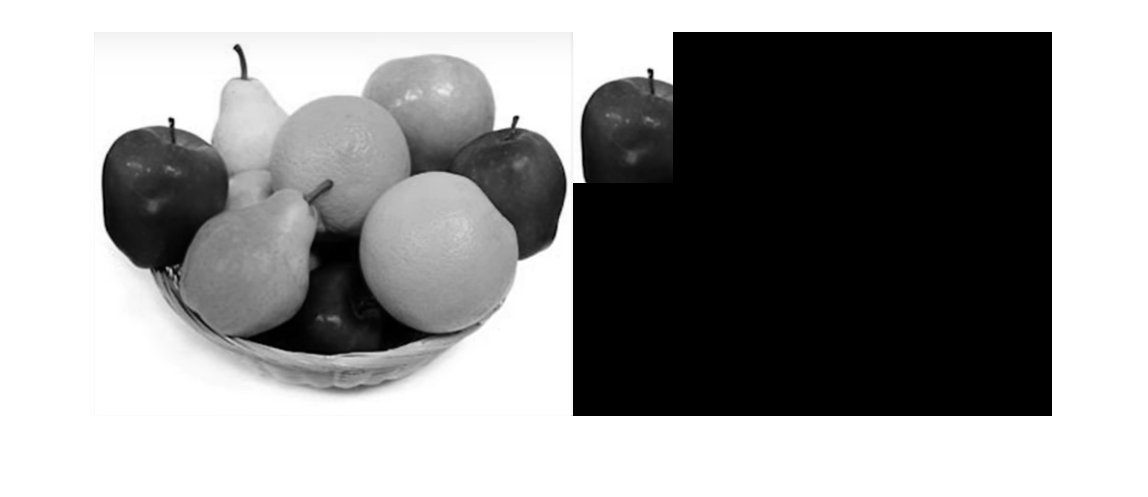

fruits = rgb2gray(imread("fruits.PNG"));
apple = fruits(50:200, 1:100);
imshowpair(fruits,apple,'montage');

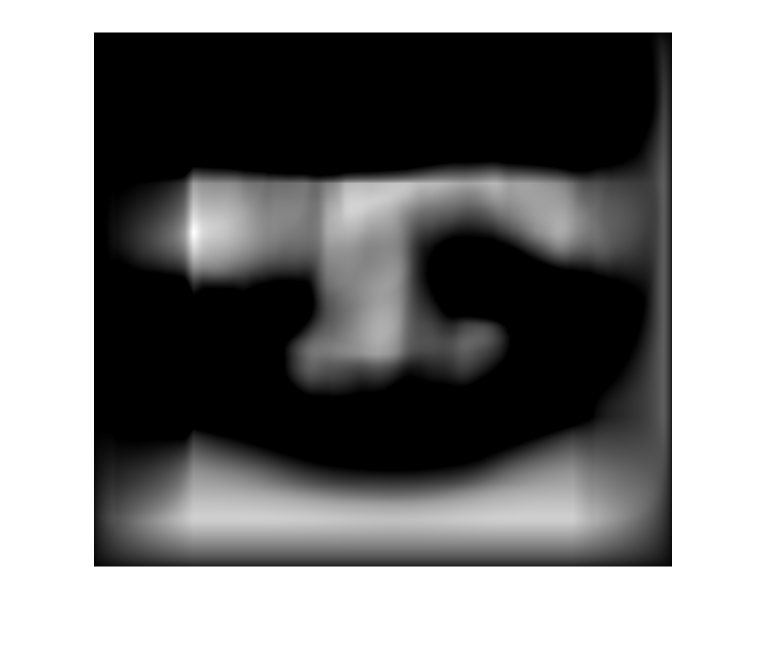

 c = normxcorr2(apple,fruits);
 imshow(c);

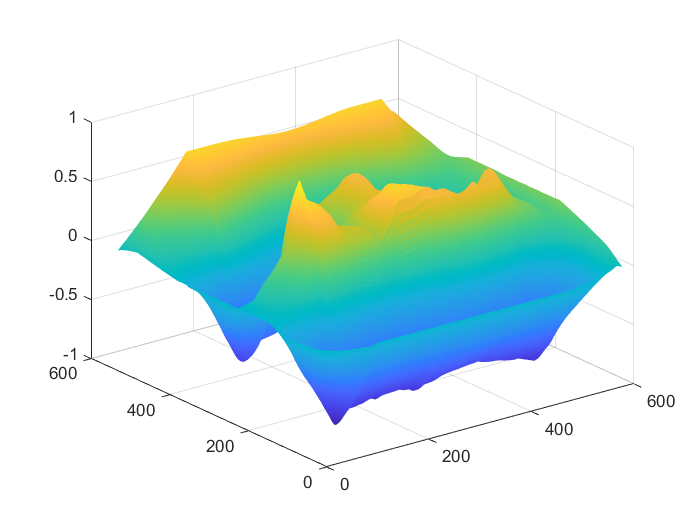

 figure, surf(c), shading flat;

s = [-1 0 0 1 1 1 0];
t = [1 1 0];
disp('Signal:'), disp([1:size(s,2);s]);

Signal:
     1     2     3     4     5     6     7
    -1     0     0     1     1     1     0



disp('Template:'), disp([1:size(t,2);t]);

Template:
     1     2     3
     1     1     0



c1 = normxcorr2(t,s);
disp([1:size(c1,2);c1]);

    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
         0   -1.0000   -0.5000   -1.0000   -0.5000         0    1.0000    0.8660    0.5000



[maxValue rawindex] = max(c1);

normxcorr2 starts when the last bit of template touches signal and ends when first bit of template touches last bit of signal, so we 4 extra values. to get the correct index we need adjust for these extra ones.

index = rawindex-size(t,2)+1;
disp(maxValue);

     1



disp(index);

     5



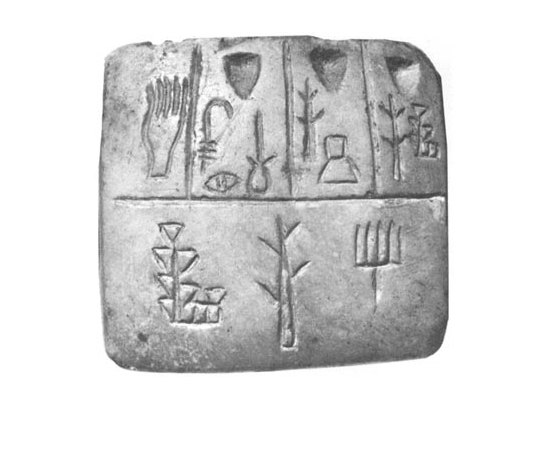

img = imread("ud810\course_images\tablet.png");
imshow(img);

glyph = img(75:165, 150:185);
imshow(glyph);
c = normxcorr2(glyph,img);
[yRaw , xRaw] = find(c == max(c(:)));
yIndex = yRaw- size(glyph,1) + 1

yIndex = 75

xIndex = xRaw- size(glyph,2) +1

xIndex = 150

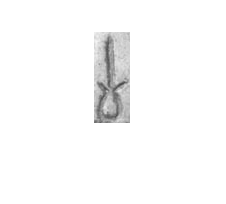

colormap("gray"), imagesc(img);

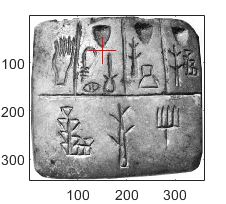

hold on; 
plot(xIndex, yIndex, 'r+', 'markersize', 16);
hold off;